In this document we will explore the concept of a "valid design" for a single variable-curvature segment. We will first implement the forward kinematics of a rod with linear curvature. Then, we will compute the externally induced forces and moments along it at each point, and plot these points in the reaction space. Finally, we will compute the internal reaction forces along an arm held at that shape, and also plot these points within the reaction space.

% Define arm base curve
% First we define the arm's design
rho_outer = 0.08;
rho_inner = 0.015;

rhos = [-rho_outer, -rho_inner, rho_inner, rho_outer];
mat_A = [
1, 1, 1, 1;
0, 0, 0, 0;
-rhos;
];

f_bellow = @JacobBellowMechanics.actuator_force;
f_muscle = @GinaMuscleMechanics.actuatorForce_key;
fs = {f_bellow, f_muscle, f_muscle, f_bellow};

l_0 = 0.5;

g_0 = Pose2.hat([0, 0, -pi/2]);
N_poses = 10;

% Combine the design parameters into a struct
struct_design = struct();
struct_design.mat_A = mat_A;
struct_design.l_0 = l_0;
struct_design.fs = fs;
struct_design.g_0 = g_0;
struct_design.rhos = rhos;

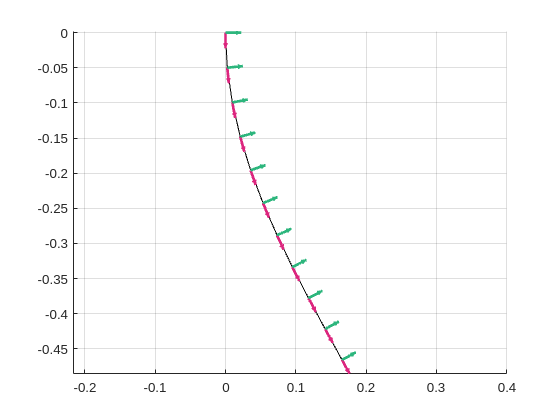

% Define the shape that the arm is held at
a = -1;
b = 1;

l = 0.5;
f_affine_curvature = @(s) [
    l*ones(size(s));
    zeros(size(s));
    a*s + b
];
s = linspace(0, 1, N_poses);
poses = f_calc_poses(g_0, f_affine_curvature, N_poses);
segment_twists = f_affine_curvature(s);

ax = axes(figure());
plot_poses(poses, ax);
grid on

Now let's apply a load to the tip of this rod and consider the reactions across it:

Q_tip = [0; -10; 0];
q = calc_external_wrench(segment_twists, Q_tip, g_0);
a_target = -q;

Now given the pressures of each muscle in the arm, compute the internal reaction force supplied along the length of the arm

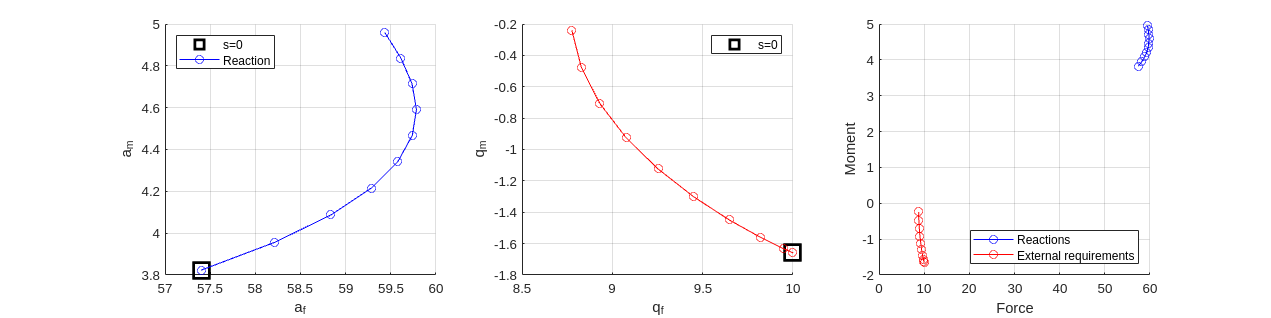

p = [15; 0; 15; 0]; %kPa
reaction_forces = calc_reaction_wrench(segment_twists, p, struct_design);

% Now we plot the two against each other
figure("position", [0, 0, 1600, 400])
subplot(1, 3, 1)
hold on
plot(reaction_forces(1, 1), reaction_forces(3, 1), "ksquare", "markersize", 15, "linewidth", 3)
plot(reaction_forces(1, :), reaction_forces(3, :), "b-o")
legend("s=0", "Reaction", location="Northwest")
xlabel("a_f")
ylabel("a_m")
grid on

subplot(1, 3, 2)
hold on
plot(q(1, 1), q(3, 1), "ksquare", "markersize", 15, "linewidth", 3);
plot(q(1, :), q(3, :), 'r-o');
xlabel("q_f")
ylabel("q_m")
legend("s=0")
grid on

subplot(1, 3, 3)
hold on
plot(reaction_forces(1, :), reaction_forces(3, :), "b-o");
plot(q(1, :), q(3, :), "r-o");
xlabel("Force")
ylabel("Moment")
legend("Reactions", "External requirements", location="southeast")
grid on

The crucial questions for extending our previous work to the variable curvature arm are:

- What will happen to this plot when we traverse the pressure contour? 

- How can we read "designability" from the variable curvature arm's pressure contour?

Now let's try doing this for a whole range of pressures along the pressure contour

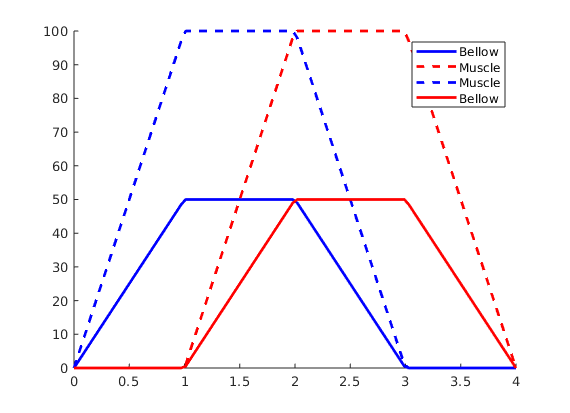

N_edge = 25;
t = linspace(0, 4, 4*N_edge);
p_max_bellow = 50;
p_max_muscle = 100;
p_max = [p_max_bellow, p_max_muscle, p_max_muscle, p_max_bellow];
ps = outline_pressure_space(p_max, [1, 2, 1, 2], N_edge);
figure()
hold on
plot(t, ps(1, :), "b-", "linewidth", 2);
plot(t, ps(2, :), "r--", "linewidth", 2);
plot(t, ps(3, :), "b--", "linewidth", 2);
plot(t, ps(4, :), 'r-', "linewidth", 2);
set(gcf, "visible", true)
legend("Bellow", "Muscle", "Muscle", "Bellow")

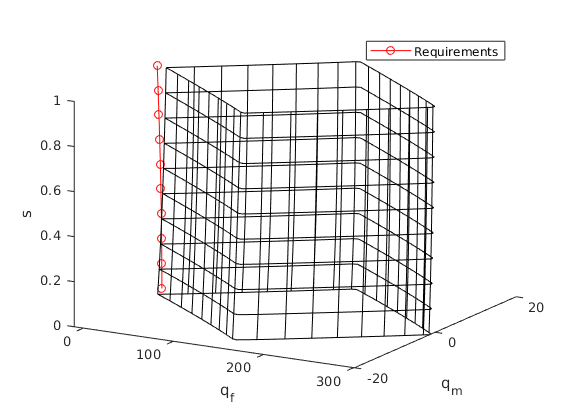

mat_3d_rxns = zeros([size(reaction_forces), length(t)]);
for i = 1 : size(ps, 2)
    mat_3d_rxns(:, :, i) = calc_reaction_wrench(segment_twists, ps(:, i), struct_design);
end

% For each element within the segment, track how the reactions moved as we
% traversed the pressure contour.
paths_qf = zeros(N_poses, length(t));
paths_qm = zeros(N_poses, length(t));
text_labels = cell(1, N_poses);
for i = 1 : N_poses
    paths_qf(i, :) = squeeze(mat_3d_rxns(1, i, :));
    paths_qm(i, :) = squeeze(mat_3d_rxns(3, i, :));
    text_labels{i} = sprintf("s=%.2f", s(i));
end

mat_s = repmat(s, [N_edge*4, 1]);

figure()
hold on
plot3(a_target(1, :), a_target(3, :), s, 'r-o')
plot3(paths_qf(:, 1:3:end)', paths_qm(:, 1:3:end)', s, 'k');
plot3(paths_qf', paths_qm', mat_s, 'k');

xlabel("q_f")
ylabel("q_m")
zlabel("s")
legend("Requirements")
view(30, 20)
set(gcf, "visible", true)

% Find the pressure that will minimize the force residuals for when the arm
% is held at this shape.
tic
f_cost_pressure = @(pres) sum(vecnorm(check_equilibrium(segment_twists, Q_tip, pres, struct_design), 1));
[soln_p_min_residual] = fminunc(f_cost_pressure, [0; 0; 0; 0]);


Local minimum possible.

fminunc stopped because it cannot decrease the objective function
along the current search direction.

<stopping criteria details>


soln_a_min_residual = calc_reaction_wrench(segment_twists, soln_p_min_residual, struct_design);
toc

Elapsed time is 0.535101 seconds.


% Find the pressure such that a(s=0) = [q_f, q_m]
tic
soln_p_rxn_at_base = fmincon(@(p) cost_first_reaction_diff(segment_twists, p, struct_design, a_target), [0; 0; 0; 0], [], [], [], [], [0; 0; 0; 0], [50; 100; 100; 50]);


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


soln_a_rxn_at_base = calc_reaction_wrench(segment_twists, soln_p_rxn_at_base, struct_design);
toc

Elapsed time is 0.198143 seconds.


tic
default_segment_twists = zeros(size(segment_twists));
default_segment_twists(1, :) = l_0;
default_segment_twists(3, :) = 1e-5;

f_tip = @(p, K) cost_tip_pose_error(default_segment_twists, p, Q_tip, struct_design, poses(:, :, end), K);
tic
soln_p_closest_tip_ktheta_0 = fmincon(@(p) f_tip(p, diag([1, 1, 0])), [0; 0; 0; 0], [], [], [], [], [0; 0; 0; 0], [50; 100; 100; 50]);


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


soln_p_closest_tip_ktheta_03 = fmincon(@(p) f_tip(p, diag([1, 1, 0.03])), [0; 0; 0; 0], [], [], [], [], [0; 0; 0; 0], [50; 100; 100; 50]); 


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


soln_p_closest_tip_ktheta_06 = fmincon(@(p) f_tip(p, diag([1, 1, 0.06])), [0; 0; 0; 0], [], [], [], [], [0; 0; 0; 0], [50; 100; 100; 50]);


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


soln_p_closest_tip_ktheta_09 = fmincon(@(p) f_tip(p, diag([1, 1, 0.09])), [0; 0; 0; 0], [], [], [], [], [0; 0; 0; 0], [50; 100; 100; 50]);
toc
soln_a_closest_tip = calc_reaction_wrench(segment_twists, soln_p_closest_tip, struct_design);

opts = optimoptions("fsolve", MaxFunctionEvaluations=4e5, MaxIterations=5e3, StepTolerance=1e-8, FunctionTolerance=1e-8, Algorithm="levenberg-marquardt", Display="off");
f = @(mat_in) check_equilibrium(mat_in, Q_tip, soln_p_min_residual, struct_design);
[soln_mimic_shape, res, ~, output, J_end] = fsolve(f, default_segment_twists, opts);
if norm(res) > 0.01, disp(res), end

f = @(mat_in) check_equilibrium(mat_in, Q_tip, soln_p_rxn_at_base, struct_design);
[soln_mimic_rxns, res, ~, output, J_end] = fsolve(f, default_segment_twists, opts);
if norm(res) > 0.01, disp(res), end

f = @(mat_in) check_equilibrium(mat_in, Q_tip, soln_p_closest_tip_ktheta_0, struct_design);
[soln_closest_tip_0, res, ~, output, J_end] = fsolve(f, default_segment_twists, opts);
if norm(res) > 0.01, disp(res), end

f = @(mat_in) check_equilibrium(mat_in, Q_tip, soln_p_closest_tip_ktheta_03, struct_design);
[soln_closest_tip_03, res, ~, output, J_end] = fsolve(f, default_segment_twists, opts);
if norm(res) > 0.01, disp(res), end

f = @(mat_in) check_equilibrium(mat_in, Q_tip, soln_p_closest_tip_ktheta_06, struct_design);
[soln_closest_tip_06, res, ~, output, J_end] = fsolve(f, default_segment_twists, opts);
if norm(res) > 0.01, disp(res), end

f = @(mat_in) check_equilibrium(mat_in, Q_tip, soln_p_closest_tip_ktheta_09, struct_design);
[soln_closest_tip_09, res, ~, output, J_end] = fsolve(f, default_segment_twists, opts);
if norm(res) > 0.01, disp(res), end

ax = axes(figure());
hold on

red = [220 38 126] / 255;
blue = [100 143 255] / 255;
yellow = [255 176 0] / 255;
green = [45 182 125] / 255;

plot_poses(calc_poses(g_0, segment_twists), ax, struct(color="k", linewidth=2), true, 0.1)
plot_poses(calc_poses(g_0, soln_closest_tip_0), ax, struct(color=blue, linewidth=2, marker='square', markersize=10), true, 0.1);
plot_poses(calc_poses(g_0, soln_closest_tip_0), ax, struct(color=blue, linewidth=2, marker='square', markersize=10, handlevisibility="off"), false);
plot_poses(calc_poses(g_0, soln_closest_tip_03), ax, struct(color=blue, linewidth=2, marker='o', markersize=10), true, 0.1);
plot_poses(calc_poses(g_0, soln_closest_tip_06), ax, struct(color=blue, linewidth=2, marker='+', markersize=10), true, 0.1);
plot_poses(calc_poses(g_0, soln_closest_tip_09), ax, struct(color=blue, linewidth=2, marker='^', markersize=10), true, 0.1);
plot_poses(calc_poses(g_0, soln_mimic_shape), ax, struct(color=red, linewidth=2), true, 0.1);
plot_poses(calc_poses(g_0, soln_mimic_rxns), ax, struct(color=yellow, linewidth=2), true, 0.1);

grid on
legend("Target", "Closest tip pose, K_{\theta}=0", "Closest tip pose, K_{\theta}=0.03", "Closest tip pose, K_{\theta}=0.06", "Closest tip pose, K_{\theta}=0.09", "Closest overall rxns", "Closest rxn at base")
set(gcf, "Visible", true)

gray = [150 150 150] / 255;

figure()
hold on
plot3(a_target(1, :), a_target(3, :), s, 'k-o', "linewidth", 2)
plot3(soln_a_closest_tip(1, :), soln_a_closest_tip(3, :), s, '-o', "color", blue, "linewidth", 2)
plot3(soln_a_min_residual(1, :), soln_a_min_residual(3, :), s, '-o', "color", red, "linewidth", 2)
plot3(soln_a_rxn_at_base(1, :), soln_a_rxn_at_base(3, :), s, '-o', "color", yellow, "linewidth", 2)
plot3(paths_qf(:, 1:3:end)', paths_qm(:, 1:3:end)', s, "color", gray);
plot3(paths_qf', paths_qm', mat_s, "color", gray);

xlabel("q_f")
ylabel("q_m")
zlabel("s")
legend("Requirements", "Closest tip position", "Closest overall rxns", "Closest rxn at base")
view(-60, 15)
set(gcf, "visible", true)

## Full range of reachable reactions - evaluating actuation modes

**TODO!!! Move this into a separate notebook focused on the reaction outline**

Clearly our prism of reachable reactions is not the full space reachable reactions. However, what *is* the actual full space? 

With four actuators, the space of possible pressures is 4-dimensional hypercube. Our previous reaction moments only spanned a two-dimensional subspace within this space.

- The first way to do this is to extend the square boundary contour method for two actuators up to the boundary of the hypercube. However the hypercube has 32 edges so that's a lot of faces to consider

- The second, easier but less thorough way is through a monte-carlo method: randomly sample a lot of points in the 4D pressure space and see what reactions they produce.

% Clearly our prism is not the full reaction image. But what is the full
% reaction image?
% This begs the question: what is the actual full reaction image?
%
% We can do this in two ways: we can compute the reactions for pressures
% along the edges of the hypercube. OR, we can do a monte-carlo sampling of
% random points in the pressure space

% Sample a bunch of points in R4 bounded by [0; 0; 0; 0] and [50; 100; 100; 50]
rng(100);
p_max = [50, 100, 100, 50];
N_ps = 1000;
ps_monte = diag(p_max) * betarnd(0.2, 0.2, 4, N_ps); % By using a beta distribution we can bias towards the edges

figure("Position", [0, 0, 1200, 400])
subplot(1, 2, 1)
scatter(ps_monte(1, :), ps_monte(4, :));
xlabel("Bellow 1 (kPa)")
ylabel("Bellow 2 (kPa)")

subplot(1, 2, 2)
scatter(ps_monte(2, :), ps_monte(3, :));
xlabel("Muscle 1 (kPa)")
ylabel("Muscle 2 (kPa)")
set(gcf, "Visible", true)

mat_rxns_3d_monte = zeros(3, N_poses, N_ps);
paths_qf_monte = zeros(N_poses, N_ps);
paths_qm_monte = zeros(N_poses, N_ps);

for i = 1 : N_ps
    % For each pressure, compute the corresponding reactions
    mat_rxns_3d_monte(:, :, i) = calc_reaction_wrench(segment_twists, ps_monte(:, i), struct_design);
end

for i = 1 : N_poses
    paths_qf_monte(i, :) = squeeze(mat_rxns_3d_monte(1, i, :));
    paths_qm_monte(i, :) = squeeze(mat_rxns_3d_monte(3, i, :));
end

figure()
hold on
mat_s_monte = repmat(s, [N_ps, 1]);
plot3(paths_qf_monte, paths_qm_monte, mat_s_monte);
plot3(paths_qf(:, 1:3:end)', paths_qm(:, 1:3:end)', s, 'k');
plot3(paths_qf', paths_qm', mat_s, 'k');
xlabel("q_f")
ylabel("q_m")
grid on
set(gcf, "Visible", true)

% Find the points that are on the outline of the base level, and then find
% their corresponding pressures. This will tell us which pressures to focus
% on.
bnd_qs = boundary(paths_qf_monte(1, :)', paths_qm_monte(1, :)', 0.1);
c = linspace(1, 10, length(bnd_qs));

figure("Position", [0, 0, 1500, 500])
subplot(1, 3, 1);
scatter(paths_qf_monte(1, bnd_qs), paths_qm_monte(1, bnd_qs), 75, c, "filled");
xlabel("q_f")
ylabel("q_m")

subplot(1, 3, 2)
scatter(ps_monte(1, bnd_qs), ps_monte(4, bnd_qs), 75, c, "filled");
xlabel("Bellow 1 (kPa)")
ylabel("Bellow 2 (kPa)")

subplot(1, 3, 3)
scatter(ps_monte(2, bnd_qs), ps_monte(3, bnd_qs), 75, c, "filled");
xlabel("Muscle 1 (kPa)")
ylabel("Muscle 2 (kPa)")
set(gcf, "Visible", true)

## Reaction prism of a reachable shape

By this point I think we are reasonably convinced that this shape is not reachable, even though the algorithm to prove that took a minute to run (and that's just for a single segment!). To complete our understanding, let us now examine the reaction prism of a shape that we *can* reach. In this case, we will consider that of the previously found shape tip-pose closest to the previous target.

mat_rxns_closest_tip = zeros([size(reaction_forces), length(t)]);
for i = 1 : length(t)
    mat_rxns_closest_tip(:, :, i) = calc_reaction_wrench(soln_closest_tip_0, ps(:, i), struct_design);
end

% For each element within the segment, track how the reactions moved as we
% traversed the pressure contour.
paths_qf_closest_tip = zeros(N_poses, length(t));
paths_qm_closest_tip = zeros(N_poses, length(t));
text_labels = cell(1, N_poses);
for i = 1 : N_poses
    paths_qf_closest_tip(i, :) = squeeze(mat_rxns_closest_tip(1, i, :));
    paths_qm_closest_tip(i, :) = squeeze(mat_rxns_closest_tip(3, i, :));
    text_labels{i} = sprintf("s=%.2f", s(i));
end

rxns_closest_tip = calc_reaction_wrench(soln_closest_tip_0, soln_p_closest_tip_ktheta_0, struct_design);
q_closest_tip = -calc_external_wrench(soln_closest_tip_0, Q_tip, struct_design.g_0);

figure("Position", [0, 0, 1200, 400])
subplot(1, 2, 1)
hold on
plot3(q_closest_tip(1, :), q_closest_tip(3, :), s, 'k-o', "linewidth", 2)
plot3(rxns_closest_tip(1, :), rxns_closest_tip(3, :), s, '-o', "color", blue, "linewidth", 2)
plot3(paths_qf_closest_tip(:, 1:3:end)', paths_qm_closest_tip(:, 1:3:end)', s, "color", gray);
plot3(paths_qf_closest_tip', paths_qm_closest_tip', mat_s, "color", gray);
xlabel("q_f")
ylabel("q_m")
zlabel("s")
legend("Requirements", "Closest possible")
view(-60, 15)
set(gcf, "visible", true)

ax = subplot(1, 2, 2);
hold on

plot_poses(calc_poses(g_0, segment_twists), ax, struct(color="k", linewidth=2), true, 0.1)
plot_poses(calc_poses(g_0, soln_closest_tip_0), ax, struct(color=blue, linewidth=2), true, 0.1);

grid on
legend("Requirements", "Arm 2")
set(gcf, "Visible", true)

## Conclusion

**Summary:**

- In this document we first developed a state-free implementation of the collocation-based Cosserat rod model with non-linear elasticity, including its constituent reaction and external wrench functions.

- We then explored an extension of the control-contour method (new name for "reaction-image" or "pressure-outline") to variable-curvature arms - what would it look like?

- We compared different metrics for finding control inputs for reaching the target tip pose.

- Through this we found that it is possible for an arm held in a specific shape to attain reaction wrenches outside of the area of reachable wrenches that was previously computed using actuation "modes". 

- Through more extensive testing we found that there may still be a way to identify a set of reachable wrenches by using a different set of pressure values at the "vertices" of our control space.

**Future work:**

- Conduct further testing to validate the "reaction boundary" method

- -- Do the same pressures bound >95% of reactions for different shapes or arm designs?

- -- Is the horizontal translation along s consistent across the space of reachable reaction wrenches?

function poses = f_calc_poses(g_0, f_segment_twists, N_poses)
    s = linspace(0, 1, N_poses);
    mat_segment_twists = f_segment_twists(s);
    poses = calc_poses(g_0, mat_segment_twists);
end

function ps = outline_pressure_space(max_ps, actuation_mode, N_edge)
    %%% Create a square path in pressure-space with N_edge points along each
    %%% edge using a corner definition: min_ps defines the bottom left
    %%% corner, and max_ps defines the top right corner. The path begins
    %%% and ends at the bottom left corner.
    %%%
    %%% Parameters:
    %%%  - max_ps: [60, 100, 100, 60] (kpa)
    %%%  - actuation_mode: [1 2 1 2]
    %%%  - N_edge: 50

    % Determine the phases of each trapezoid wave based on the actuation
    % modes. 
    % Currently mode-2 is defined starting a quarter period later than mode1
    phases = zeros(size(actuation_mode));
    for i = 1 : length(actuation_mode)
        mode_i = actuation_mode(i);
        
        if mode_i == 1
            phases(i) = 0;
        elseif mode_i == 2
            phases(i) = 1;
        end
    end
    
    t = linspace(0, 4, N_edge*4);
    ps = zeros(length(max_ps), length(t));
    for i = 1 : length(max_ps)
        ps(i, :) = max_ps(i) * trapezoid_wave(t - phases(i));
    end
end

function sig = trapezoid_wave(s)
    %%% Sample a trapzoid wave with period 1s at times s.
    %%% The trapezoid has amplitude 0.5 and is centered at 0.5
    %%% ie, it switches between 0 and 1.
    s = mod(s, 4);
    sig = zeros(size(s));
    for i = 1 : length(s)
        s_i = s(i);
        
        if s_i < 1
            sig(i) = 1 * (s_i);
        elseif (s_i >= 1) && (s_i < 2)
            sig(i) = 1;
        elseif (s_i >= 2) && (s_i < 3)
            sig(i) = -1 * (s_i - 2) + 1;
        else
            sig(i) = 0;
        end
    end
end

function cost = cost_first_reaction_diff(twists, pressure, struct_design, a_target)
    rxns = calc_reaction_wrench(twists, pressure, struct_design);
    cost = norm(rxns(:, 1) - a_target(:, 1));
end

function cost = cost_tip_pose_error(twists_0, pressure, Q_tip, struct_design, g_target, K)
    opts = optimoptions("fsolve", MaxFunctionEvaluations=4e5, MaxIterations=5e3, StepTolerance=1e-8, FunctionTolerance=1e-8, Algorithm="levenberg-marquardt", Display="off");
    f = @(mat_in) check_equilibrium(mat_in, Q_tip, pressure, struct_design);
    
    soln = fsolve(f, twists_0, opts);
    
    poses = calc_poses(struct_design.g_0, soln);
    delta_g_extrinsic = Pose2.vee(poses(:, :, end)) - Pose2.vee(g_target);
    cost = delta_g_extrinsic' * K * delta_g_extrinsic;
    %delta_g = inv(poses(:, :, end)) * g_target;
    %cost = norm(Twist2.vee(logm(delta_g)));
end

function struct_design_out = make_antagonistic_struct_design(struct_design_base, design_rl)
    struct_design_out = struct_design_base;
    struct_design_out.rhos  = [design_rl(1), 0.02, 0.02, design_rl(1)]; % Here we just sweep the outer radius
    struct_design_out.l_0 = design_rl(2);
end